# Main Code For Controller Testing

## Initialization

clear 
close all
clc


set_param('full_system', "FastRestart", "off");


## Parameters Setting

% Model Parameters

% Posture regulation strategy filename            
% Available options for easy testing:
posture = 'posture_subsys'; 
% posture = 'caertesian_subsys';

% Trajectory tracking strategy filename
% Available options for easy testing:
trajectory = 'feed_lin_sagittal_sub';
% trajectory = 'feed_lin_double_deriv_sub';
% trajectory = 'trajectory_tracking_linear_sub';
% trajectory = 'trajectory_tracking_non_linear_sub'; 


distance_threshold = 4;                 % Distance threshold for control strategy switch

% Controller Gains

sagittal_K = [10; 5];                   % Sagittal Axis Controller Gain

double_deriv_Kp = [2 0; 0 5];           % Double Derivative Controller Gains
double_deriv_Kd = [5 0; 0 5];

csi = 1/sqrt(2);                        % (Non)Linear Trajectory Tracking Dampening Factor
a = 5;                                  % " Gain

b = 2;                                  % " Gain


% Test Parameters

N = 150;                                % Number of test runs for validation


% !!! need clarification !!!
delta = 0.01*pi;
results = zeros(N,10);


## Model Control Strategy Setting

% vvv DON'T CHANGE THIS CODE IF YOU DON'T KNOW WHAT YOU ARE DOING !!! vvv

set_param('full_system', "FastRestart", "off");

% Change the posture regulation strategy
set_param('full_system/Agent 1/PR', 'ReferencedSubsystem', posture);

% Change the trajectory tracking strategy
set_param('full_system/Agent 1/TT', 'ReferencedSubsystem', trajectory);

% Save model
 save_system('full_system', 'SaveDirtyReferencedModels', 'on')

% ^^^ --------------------------------------------------------------- ^^^


## Model Validation Through Random Initial Condition Generation

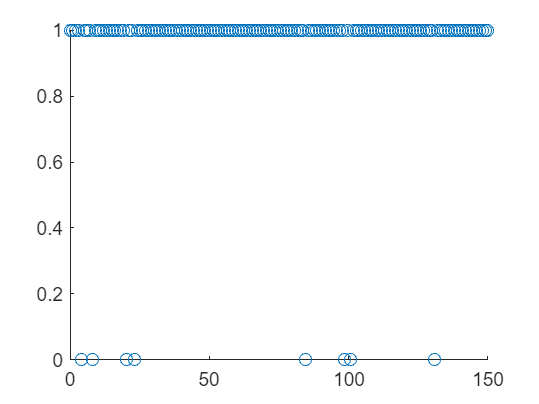

w = warning('off','all');
set_param('full_system', "FastRestart","on");

for i=1:N
    initial_conditions_1 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_2 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    initial_conditions_3 = [randi([-11 11],1,2) , (2*pi - delta)*rand(1,1)];
    

    initial_conditions_trans_1 = state_transformation([0,0,0], initial_conditions_1);
    initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
    initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);

    out = sim('full_system', "StopTime", "10");
    warning(w);
    check_convergence = out.check.signals.values(end,1);
    
    results(i,:) = [initial_conditions_1 initial_conditions_2 initial_conditions_3 check_convergence];
    
end

x = linspace(0, N, N);

figure
scatter(x,results(:, 10), "Marker","o")


set_param('full_system', "FastRestart", "off");



## Analytics

successes = sum(results(:, 10));
failures = N - successes;
success_rate = 100 * successes / N

success_rate = 94.6667


bad_ic = zeros(failures, 10);
t=1;

for i=1:N 
    if results(i,10)==0 
        bad_ic(t,:) = [results(i,:)];
        t = t+1;
    end
end

##   Visualization of a Single Run

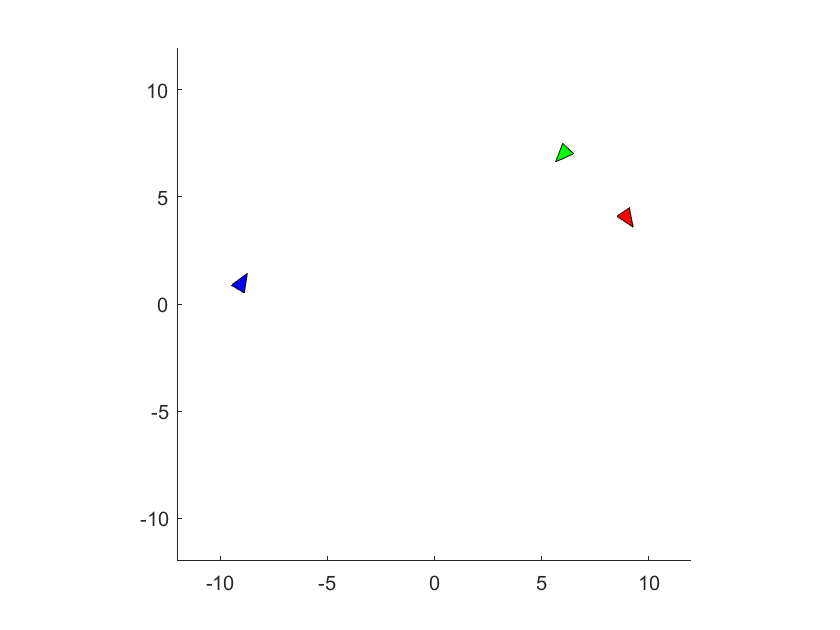

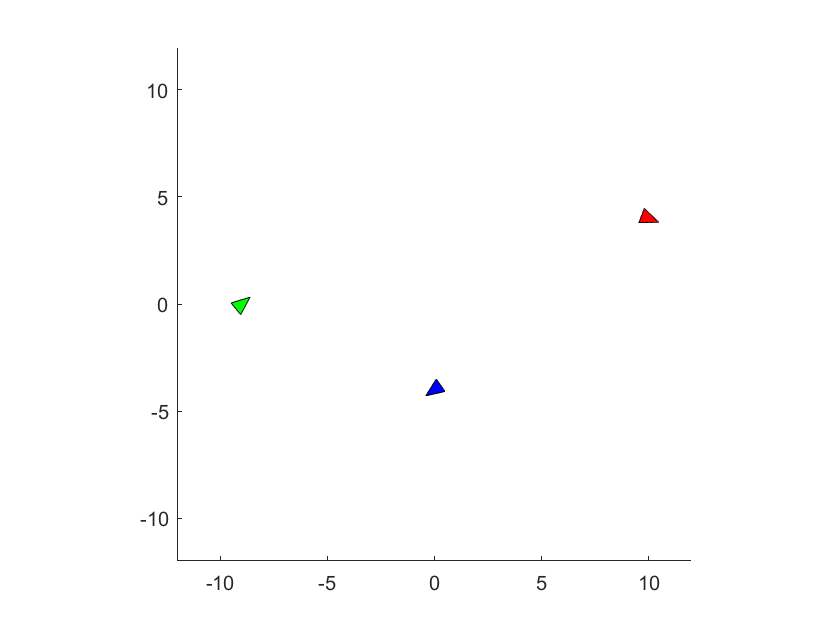

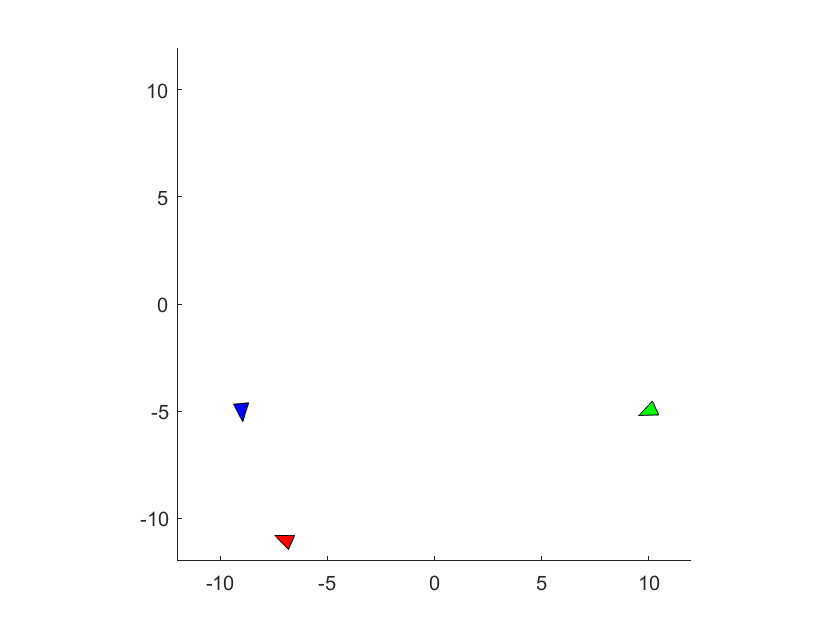

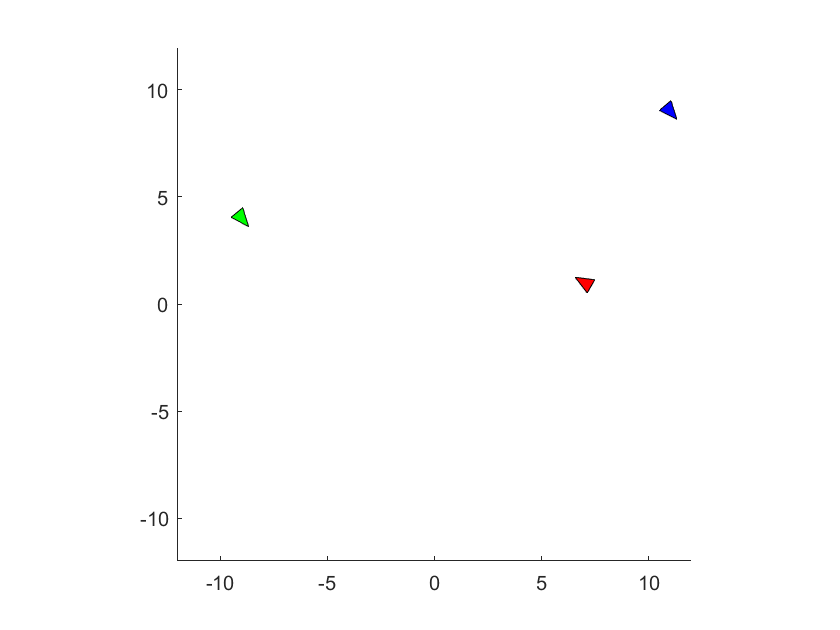

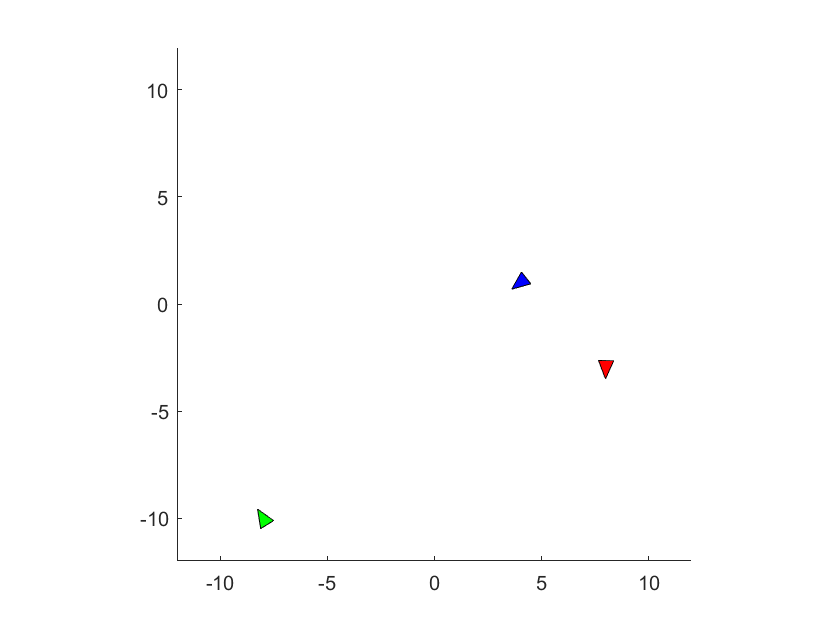

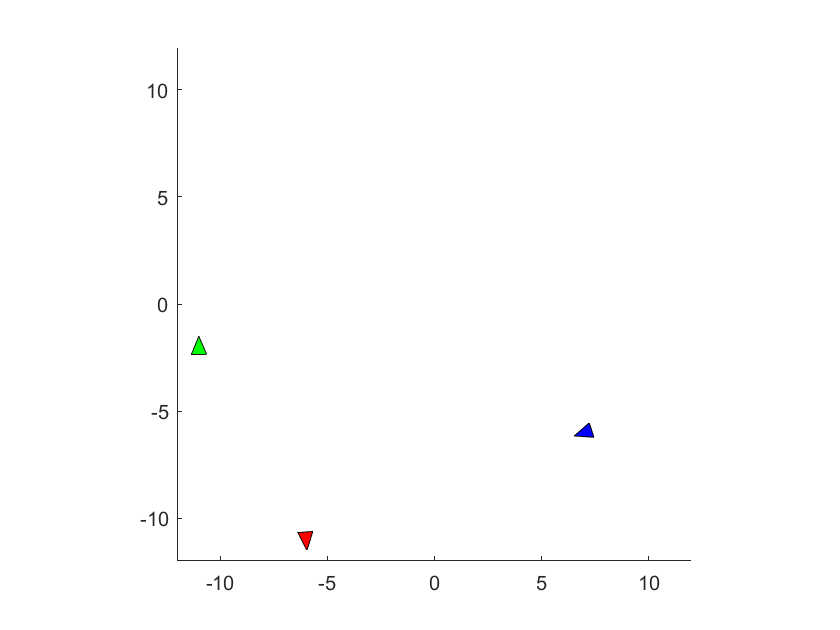

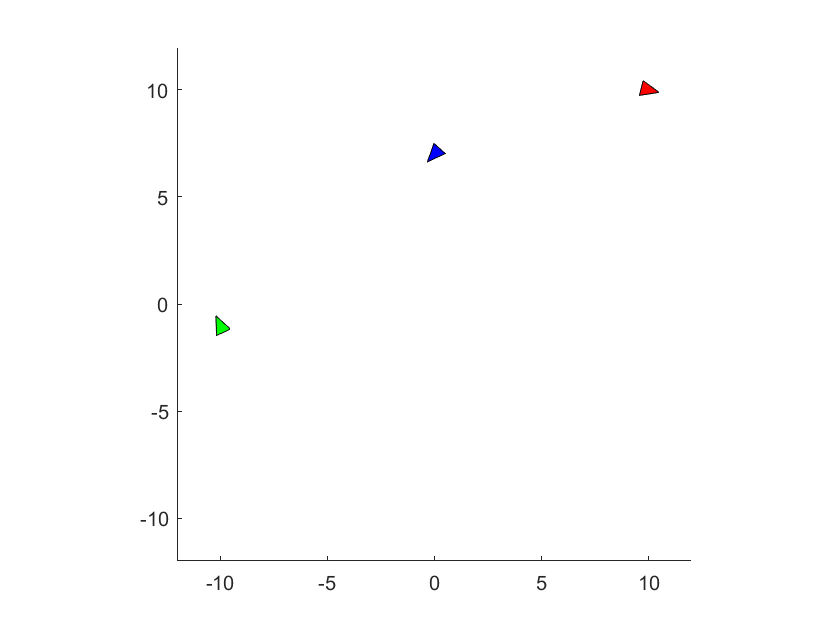

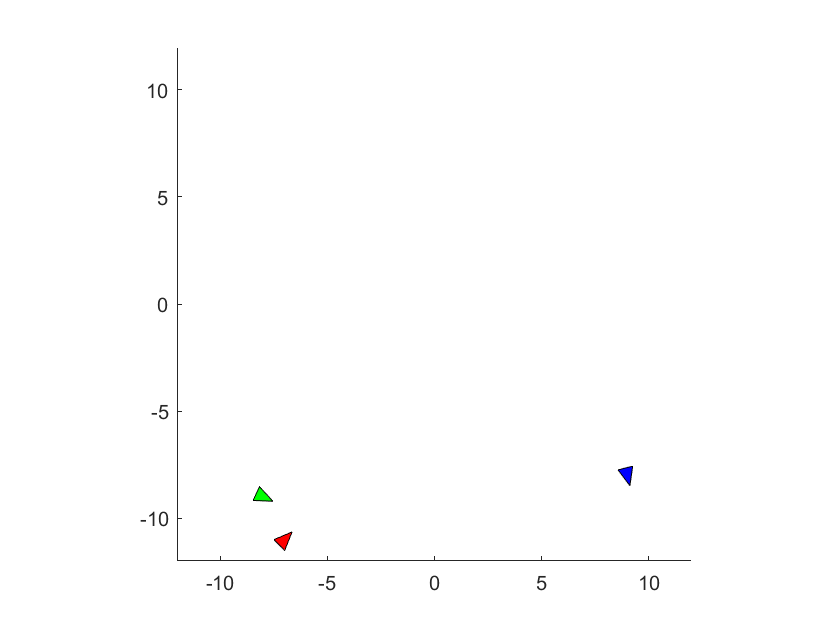

set_param('full_system', "FastRestart","on");

for i=1:failures

    a = [-0.3536 -0.3536]';
    b = [.5 0]';
    c = [-0.3536 0.3536]';
    P = [a b c];
    p = [];

    figure
    x1 = bad_ic(i,1);
    y1 = bad_ic(i,2);
    theta1 = bad_ic(i,3);
    R1 = [ cos(theta1) -sin(theta1); sin(theta1) cos(theta1)];
    Prot1 = R1*P;
    Prot_trasl1 = Prot1 + [ones(1,3)*x1; ones(1,3)*y1];
    p = patch(Prot_trasl1(1,:),Prot_trasl1(2,:),'b');

    x2 = bad_ic(i,4);
    y2 = bad_ic(i,5);
    theta2 = bad_ic(i,6);
    R2 = [ cos(theta2) -sin(theta2); sin(theta2) cos(theta2)];
    Prot2 = R2*P;
    Prot_trasl2 = Prot2 + [ones(1,3)*x2; ones(1,3)*y2];
    p = patch(Prot_trasl2(1,:),Prot_trasl2(2,:),'r');


    x3 = bad_ic(i,7);
    y3 = bad_ic(i,8);
    theta3 = bad_ic(i,9);
    R3 = [ cos(theta3) -sin(theta3); sin(theta3) cos(theta3)];
    Prot3 = R3*P;
    Prot_trasl3 = Prot3 + [ones(1,3)*x3; ones(1,3)*y3];
    p = patch(Prot_trasl3(1,:),Prot_trasl3(2,:),'g');

    axis square
    xlim([-12.0 12.0])
    ylim([-12.0 12.0])
    
    
    initial_conditions_1 = [x1, y1, theta1];
    initial_conditions_2 = [x2, y2, theta2];
    initial_conditions_3 = [x3, y3, theta3];
    

    initial_conditions_trans_1 = state_transformation([0,0,0], initial_conditions_1);
    initial_conditions_trans_2 = state_transformation([0,0,0], initial_conditions_2);
    initial_conditions_trans_3 = state_transformation([0,0,0], initial_conditions_3);

    
    out = sim('full_system', "StopTime", "10");
    w = waitforbuttonpress;                     % Aspetta che si prema un tasto per passare al successivo, non chiudere il plot 
end                                             % che viene creato senno' da errore (non ho idea del motivo)